Load data


% load NPS value
main_dir = '/Volumes/spacetop_projects_cue';
NPSdf = readtable(fullfile(main_dir, 'analysis/fmri/nilearn/deriv01_signature/rampup_plateau/signature-NPSpos_sub-all_runtype-pvc_event-stimulus.tsv'),...
    'FileType', 'text', 'Delimiter', ',');

% load behavioral value
behdf = readtable(fullfile('/Users/h/Documents/projects_local/cue_expectancy','data/beh/sub-all_task-all_epoch-stim_events.tsv'), ...
    'FileType', 'text', 'Delimiter', '\t');
% calculate intersection
mergedf = innerjoin(NPSdf, behdf, 'Keys', 'singletrial_fname');




% trim based on value and remove if na

% plot the values
pain_idx = strcmpi(mergedf.runtype, 'pain');
pain_only = mergedf(pain_idx, :);
paindf = pain_only(~ismember(pain_only.sub, {'sub-0002'}), :);
%% contrast code
% Create a mapping from strings to numbers
mapper = containers.Map({'high_stim', 'med_stim', 'low_stim'}, [1, 0, -1]);

% Iterate over the stimulusintensity column and apply the mapping
for i = 1:height(paindf)
    if isKey(mapper, paindf.stimulusintensity{i})
        paindf.stim_con(i) = mapper(paindf.stimulusintensity{i});
    else
        paindf.stim_con(i) = NaN; % Handle unexpected or missing values
    end
end


mapper = containers.Map({'high_cue', 'low_cue'}, [1, -1]);

% Iterate over the stimulusintensity column and apply the mapping
for i = 1:height(paindf)
    if isKey(mapper, paindf.cue{i})
        paindf.cue_con(i) = mapper(paindf.cue{i});
    else
        paindf.cue_con(i) = NaN; % Handle unexpected or missing values
    end
end

mapper = containers.Map({'high_cue', 'low_cue'}, [1, -1]);

% Iterate over the stimulusintensity column and apply the mapping
for i = 1:height(paindf)
    if isKey(mapper, paindf.cue{i})
        paindf.cue_con(i) = mapper(paindf.cue{i});
    else
        paindf.cue_con(i) = NaN; % Handle unexpected or missing values
    end
end


%% remove NAN
paindf_clean_Y = remove_missing_behvalues(paindf, 'outcomerating');
paindf_clean_X = remove_missing_behvalues(paindf_clean_Y, 'expectrating');
paindf_clean = remove_missing_behvalues(paindf_clean_X, 'NPSpos');


% mean center
% Get unique subjects
uniqueSubs = unique(mergedf.sub);

% Loop through each subject to calculate and store the demeaned expectrating
for i = 1:length(uniqueSubs)
    subIndex = strcmp(paindf_clean.sub, uniqueSubs{i}); % Find indices of current subject
    subMean = mean(paindf_clean.expectrating(subIndex)); % Calculate mean expectrating for current subject
    paindf_clean.EXPECT_demean(subIndex) = paindf_clean.expectrating(subIndex) - subMean; % Subtract mean from each rating
    paindf_clean.EXPECT_CMC(subIndex) = subMean;
end


% paindf_clean.stimulusintensity(index)
% sublist is the list of unique values in mergedf.sub
sub_list = unique(paindf_clean.sub);
%% expect -> NPSpos -> outcome
for i= 1:length(sub_list)
    index = strcmpi(paindf_clean.sub, sub_list(i));
    model1_X{i} = paindf_clean.expectrating(index); %EXPECT_demean(index); % - mean(paindf_clean.expectrating(index)); %df.cue(index);  %
    model1_M{i} = paindf_clean.NPSpos(index); 
    model1_Y{i} = paindf_clean.outcomerating(index); 
    cov_mediation_paincue{i} = [ paindf_clean.stim_con(index) paindf_clean.cue_con(index)];
end



% 10 remove 3 sd
% ________________________________________________________
wh_outlier = cellfun(@(x) abs(x - mean(x)) > 3*std(x), model1_M, 'UniformOutput', false);

for i= 1:1:length(sub_list)
% model1_Mremovedpts{i} = model1_M{i}(wh_outlier{i});
model1_Mtrimmed{i} = model1_M{i}(~wh_outlier{i});
model1_Xtrimmed{i} = model1_X{i}(~wh_outlier{i});
model1_Ytrimmed{i} = model1_Y{i}(~wh_outlier{i});
cov_mediation_paincue_trimmed{i} = cov_mediation_paincue{i}(~wh_outlier{i});
end

% 2) remove trials less than 10
ntrials_trimmed = cellfun(@length, model1_Mtrimmed);

create_figure('ntrials', 1, 2); 
hist(ntrials_trimmed, 30)
title('Number of trials')
xlabel('Number of trials'); ylabel('Num. Subjects')

wh_remove = ntrials_trimmed < 10;
disp('removing:')

removing:


sum(wh_remove)

ans = 0

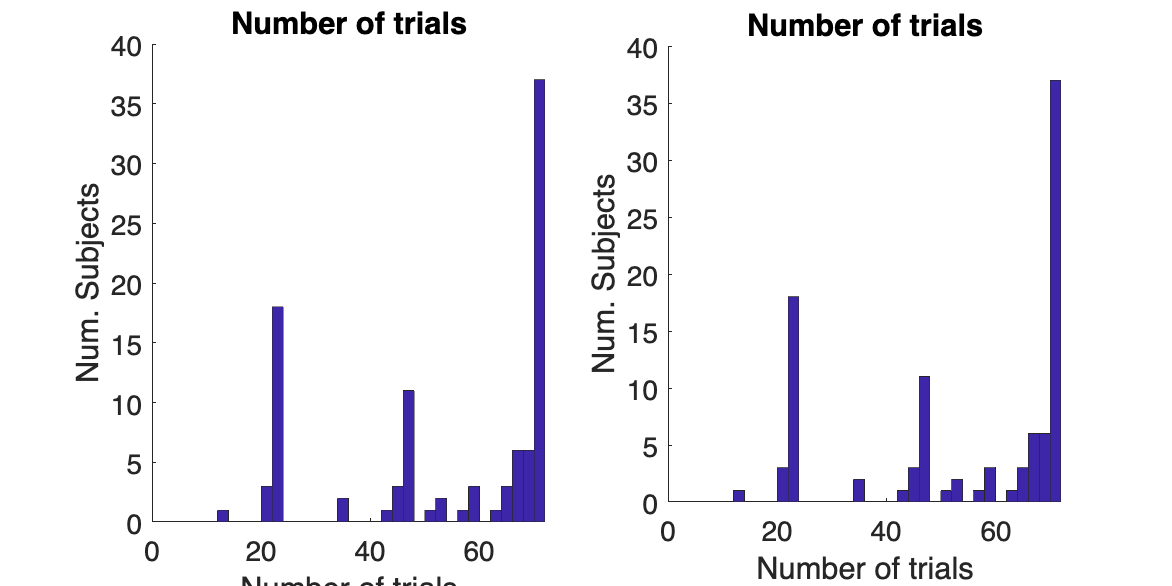


model1_X(wh_remove) = [];
model1_Xtrimmed(wh_remove) = [];
model1_Y(wh_remove) = [];
model1_Ytrimmed(wh_remove) = [];
model1_M(wh_remove) = [];
model1_Mtrimmed(wh_remove) = [];
cov_mediation_paincue(wh_remove) = [];
cov_mediation_paincue_trimmed(wh_remove) = [];

subplot(1, 2, 2); hist(ntrials_trimmed, 30)
title('Number of trials')
xlabel('Number of trials'); ylabel('Num. Subjects')


%% remove nan values from dataframes

meanx = cellfun(@nanmean, model1_Xtrimmed)';
meany = cellfun(@nanmean, model1_Ytrimmed)';
meanm = cellfun(@nanmean, model1_Mtrimmed)';
partialr = partialcorr([meanx meany meanm]);

t = array2table(partialr, 'VariableNames', {'Expect' 'Pain' 'NPSpos'});


# mediation

Mediation analysis

Observations:   1, Replications:  99
Predictor (X): Pain_Expectation, Outcome (Y): Outcome rating: Mediator (M): NPSpos

Covariates: Yes,  99 columns

Multi-level analysis.
Options:
	Multilevel weights: Yes
	Plots: Yes
	Bootstrap: Yes
	Sign perm: No
	Robust: No
	Logistic(Y): No
	Bootstrap 1st level: No
	Bootstrap or sign perm samples: 10000

Getting estimates for replications: 099 Done.
Bootstrapping 10000 samples... Min p-value is 0.000100. Adding   0 samples
 Bootstrapping...Estimating variance components based on 10000 bootstrap samples
 Done in   1 s 


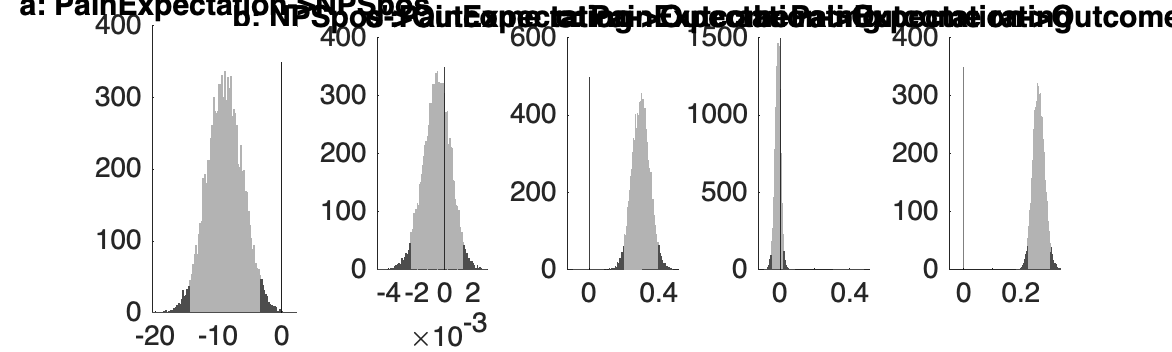

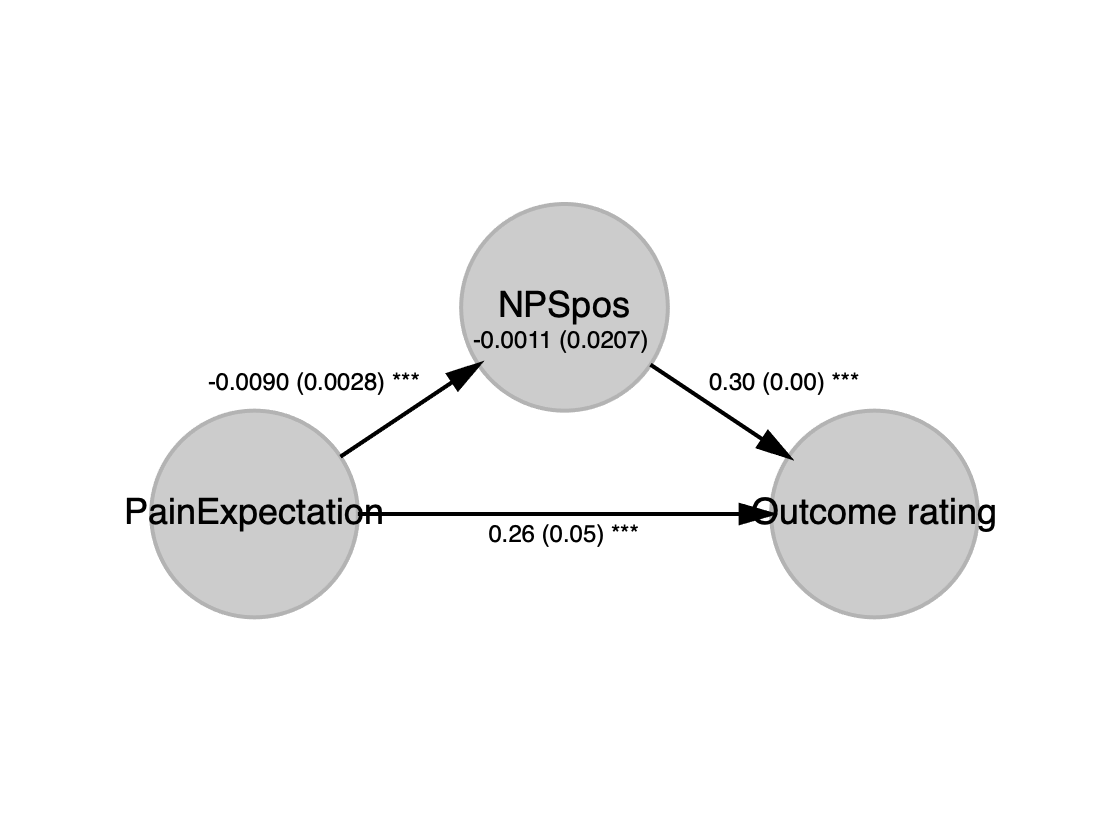

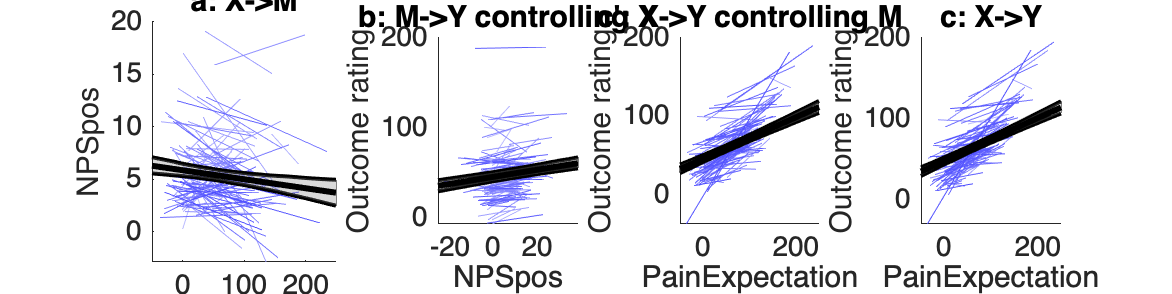

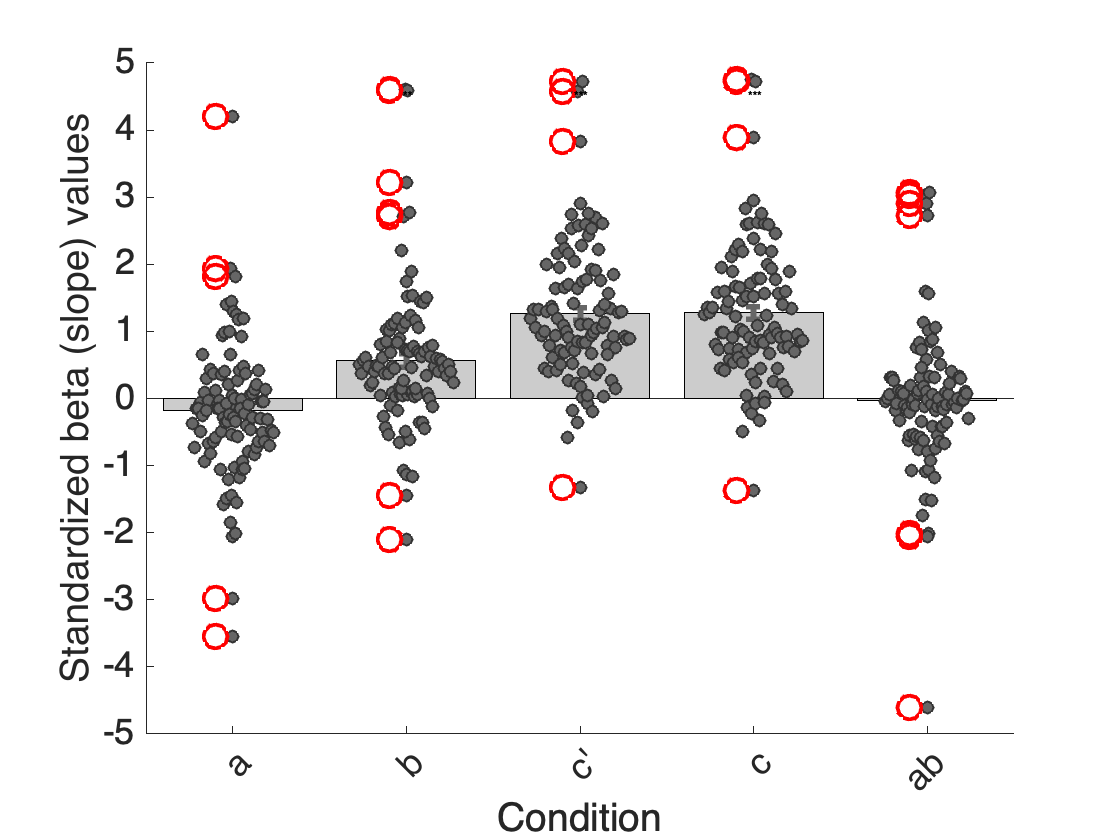

Mediation scatterplots:
Replications:  99
Covariates controlled for in all regressions:  99 predictors
Additional mediators controlled for in outcome predictions:   1 predictors


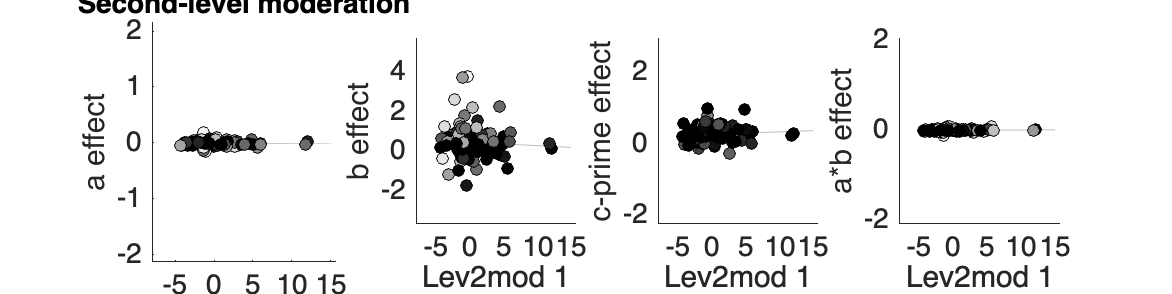


________________________________________
Average p-value tolerance (average max alpha): 0.0060

Multi-level model
	a	b	c'	c	ab	
Coeff	-0.01	0.30	0.26	0.26	-0.00	
STE	0.00	0.05	0.02	0.02	0.00	
t (~N)	-3.18	5.73	12.80	12.94	-1.07	
Z	-3.38	3.58	4.12	4.09	-1.01	
p	0.0007	0.0003	0.0000	0.0000	0.3125	

________________________________________

________________________________________
Second Level Moderator
Multi-level model
	a	b	c'	c	ab	
Coeff	-0.00	-0.01	0.01	0.01	0.00	
STE	0.00	0.02	0.01	0.01	0.00	
t (~N)	-0.49	-0.88	1.11	1.15	0.64	
Z	-0.68	-0.97	1.43	1.52	0.70	
p	0.4957	0.3298	0.1523	0.1283	0.4850	

________________________________________
Total time:   7 s



moderator = scale(meanm, 1); 
[paths_M_tolerance, stats_M_tolerance] = mediation(model1_Xtrimmed, model1_Ytrimmed, model1_Mtrimmed, ...
    'covs', cov_mediation_paincue_trimmed ,  'boot', 'verbose','plots', ...
    'names', {'Pain_Expectation' 'Outcome rating', 'NPSpos' },'L2M', moderator, 'bootsamples', 10000);


%% check:
% Obtain lengths of each trimmed variable
Ydata_lengths = cellfun(@length, model1_Ytrimmed);
Xdata_lengths = cellfun(@length, model1_Xtrimmed);
Mdata_lengths = cellfun(@length, model1_Mtrimmed);
cov_lengths = cellfun(@length, cov_mediation_paincue_trimmed);

% Create a matrix of the lengths
all_lengths = [Ydata_lengths; Xdata_lengths; Mdata_lengths; cov_lengths];

% Check if all lengths are equal across each set of variables
are_lengths_equal = all(diff(all_lengths) == 0);

% If not all lengths are equal, identify which ones differ
if ~are_lengths_equal
    [rows, cols] = find(diff(all_lengths) ~= 0);
    for i = 1:length(rows)
        fprintf('Discrepancy found in subject %d between variables %d and %d.\n', cols(i), rows(i), rows(i)+1);
    end
else
    disp('All lengths are equal.');
end

All lengths are equal.



%% check na
% Check for NaN values in each cell of the cell arrays
hasNaN_Y = cellfun(@(x) any(isnan(x)), model1_Ytrimmed);
hasNaN_X = cellfun(@(x) any(isnan(x)), model1_Xtrimmed);
hasNaN_M = cellfun(@(x) any(isnan(x)), model1_Mtrimmed);
hasNaN_cov = cellfun(@(x) any(isnan(x)), cov_mediation_paincue_trimmed);

% Summarize the NaN checks to see if any cell array contains NaN values
sumHasNaN_Y = any(hasNaN_Y);
sumHasNaN_X = any(hasNaN_X);
sumHasNaN_M = any(hasNaN_M);
sumHasNaN_cov = any(hasNaN_cov);

% Display results
disp(['model1_Ytrimmed contains NaN: ', num2str(sumHasNaN_Y)]);

model1_Ytrimmed contains NaN: 0


disp(['model1_Xtrimmed contains NaN: ', num2str(sumHasNaN_X)]);

model1_Xtrimmed contains NaN: 0


disp(['model1_Mtrimmed contains NaN: ', num2str(sumHasNaN_M)]);

model1_Mtrimmed contains NaN: 0


disp(['cov_mediation_paincue_trimmed contains NaN: ', num2str(sumHasNaN_cov)]);

cov_mediation_paincue_trimmed contains NaN: 0




%% plot
colors = seaborn_colors(length(model1_Xtrimmed));
barplot_columns(model1_X, 'nofig', 'noviolin', 'plotout', 'nostarts', 'notable', 'colors', colors, 'nobars')

ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
      point_han1: {72×99 cell}
        text_han: {72×99 cell}
       point_han: {72×99 cell}
     outlier_han: {1×95 cell}
    star_handles: [381.0001 382.0001 383.0001 384.0001 385.0001 386.0001 387.0001 388.0001 389.0001 390.0001 391.0001 392.0001 393.0001 394.0001 395.0001 396.0001 397.0001 398.0001 399.0001 400.0001 401.0001 402.0001 403.0001 404.0001 405.0001 … ]


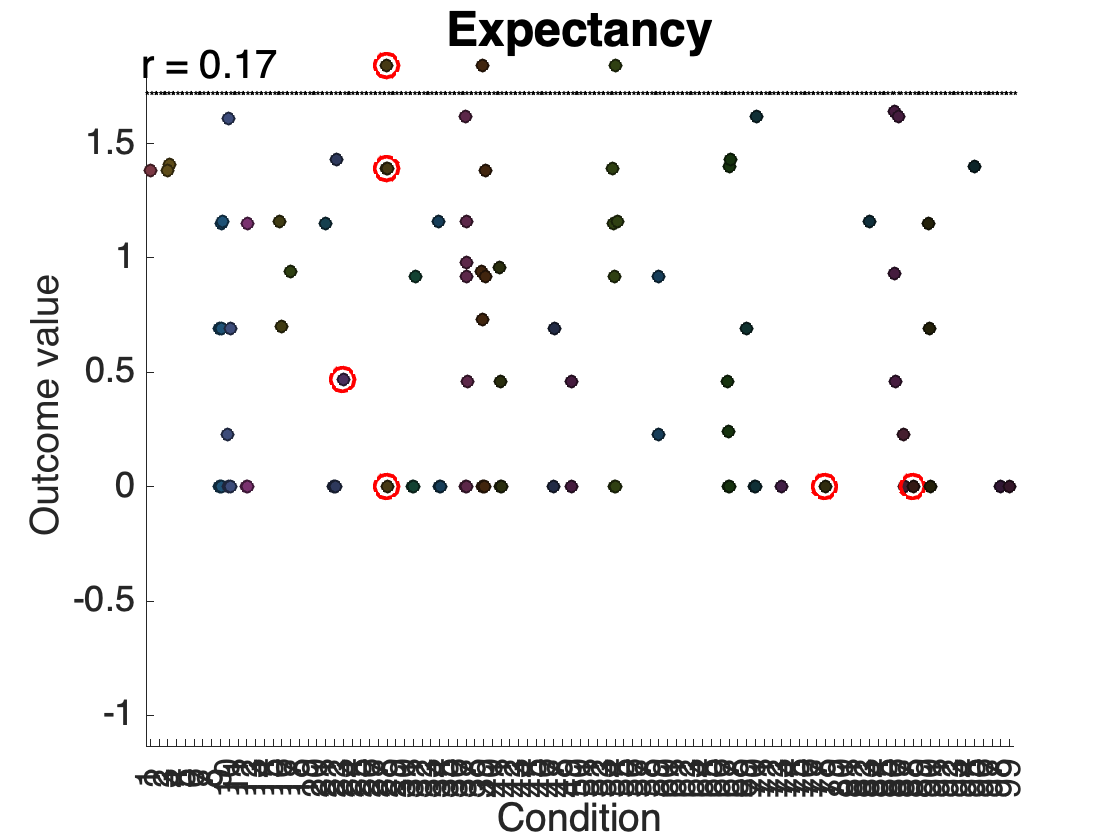

title('Expectancy');

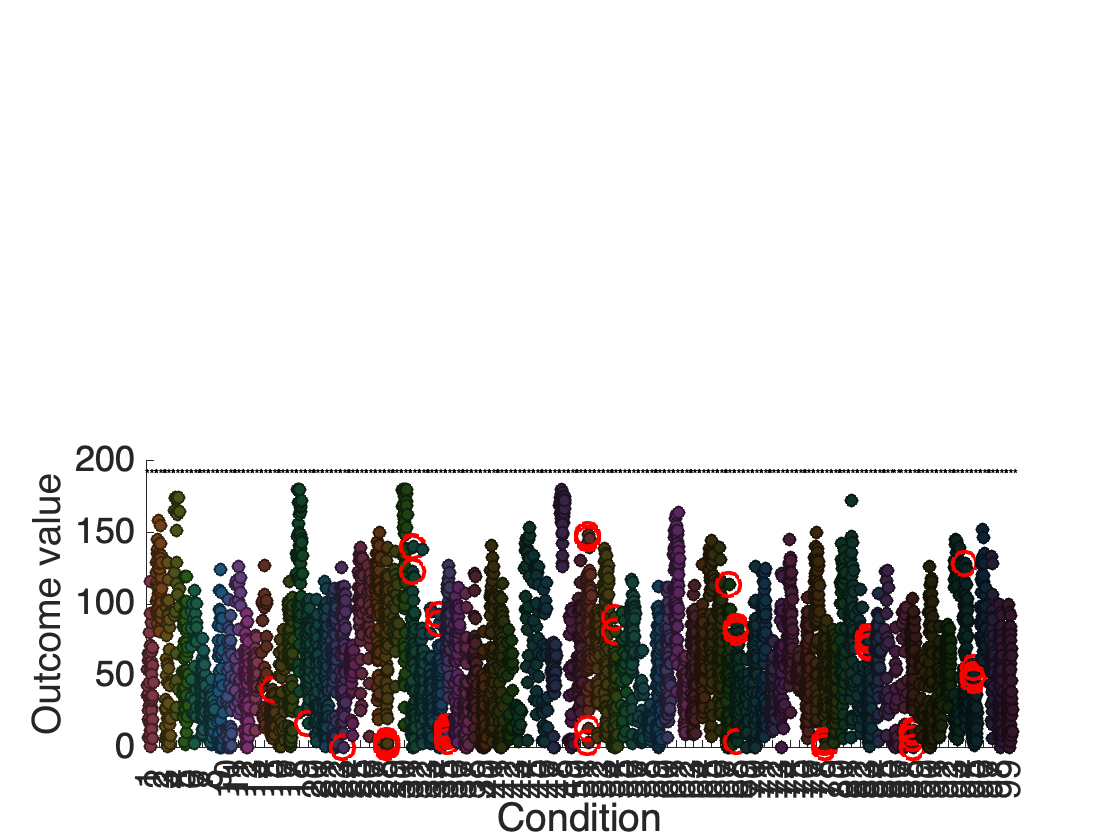

ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
      point_han1: {72×99 cell}
        text_han: {72×99 cell}
       point_han: {72×99 cell}
     outlier_han: {1×95 cell}
    star_handles: [381.0002 382.0002 383.0002 384.0002 385.0002 386.0002 387.0002 388.0002 389.0002 390.0002 391.0002 392.0002 393.0002 394.0002 395.0002 396.0002 397.0002 398.0002 399.0002 400.0002 401.0002 402.0002 403.0002 404.0002 405.0002 … ]


subplot(2,1,2);
barplot_columns(model1_Xtrimmed, 'nofig', 'noviolin', 'plotout', 'nostarts', 'notable', 'colors', colors, 'nobars')

drawnow, snapnow


%% plot

% Correlations between variables within- and between-person

meanx = cellfun(@nanmean, model1_X)';
meany = cellfun(@nanmean, model1_Y)';
meanm = cellfun(@nanmean, model1_M)';


create_figure('Expectation vs. Pain');
  set(gca, 'FontSize', 20);
  han = line_plot_multisubject(model1_X, model1_Y, 'n_bins', 5);

Warnings:

____________________________________________________________________________________________________________________________________________
X: input cells with low varability:
8 15 43 58 75
Y: input cells with low varability:
15 43 45 58 89
____________________________________________________________________________________________________________________________________________

____________________________________________________________________________________________________________________________________________
Input data:
X scaling: No centering or z-scoring
Y scaling: No centering or z-scoring
                
Transformations:
No data transformations before plot
                                                                   
Correlations:                                                      
r = 0.63 across all observations, based on untransformed input data
                                                                
Stats on slopes after transformation, s

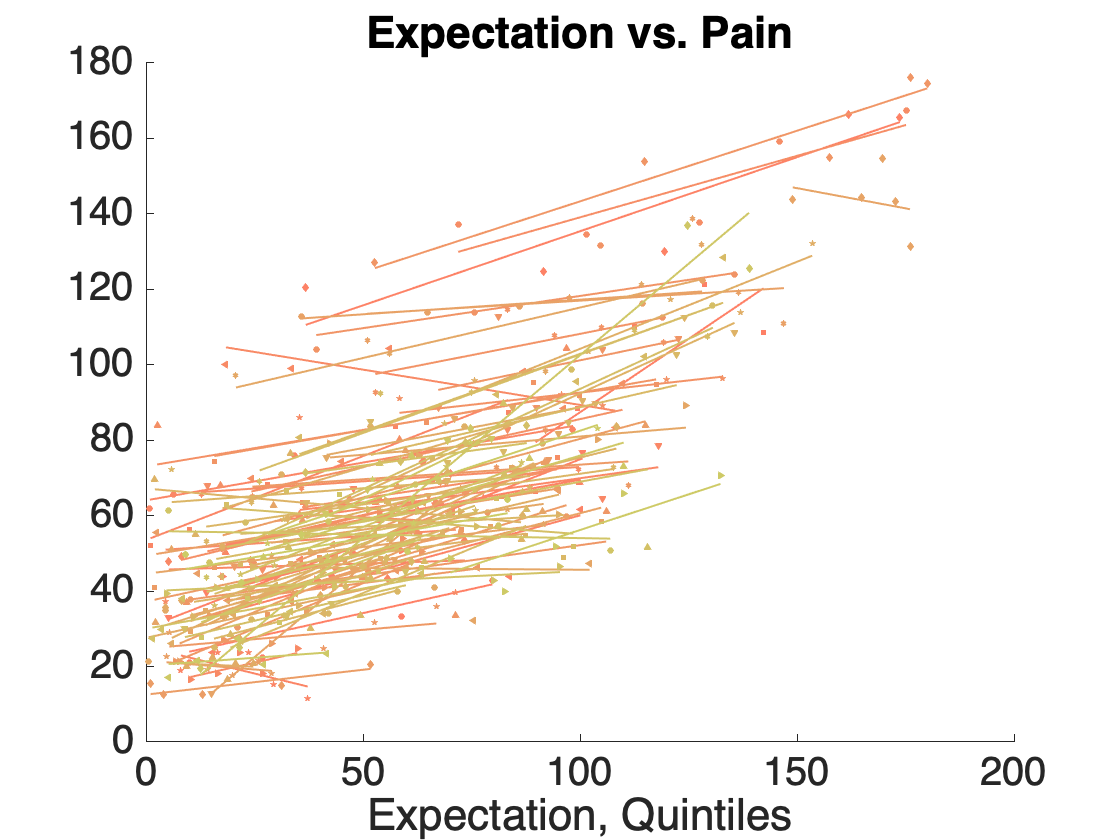

  title('Expectation vs. Pain');
  xlabel('Expectation, Quintiles');

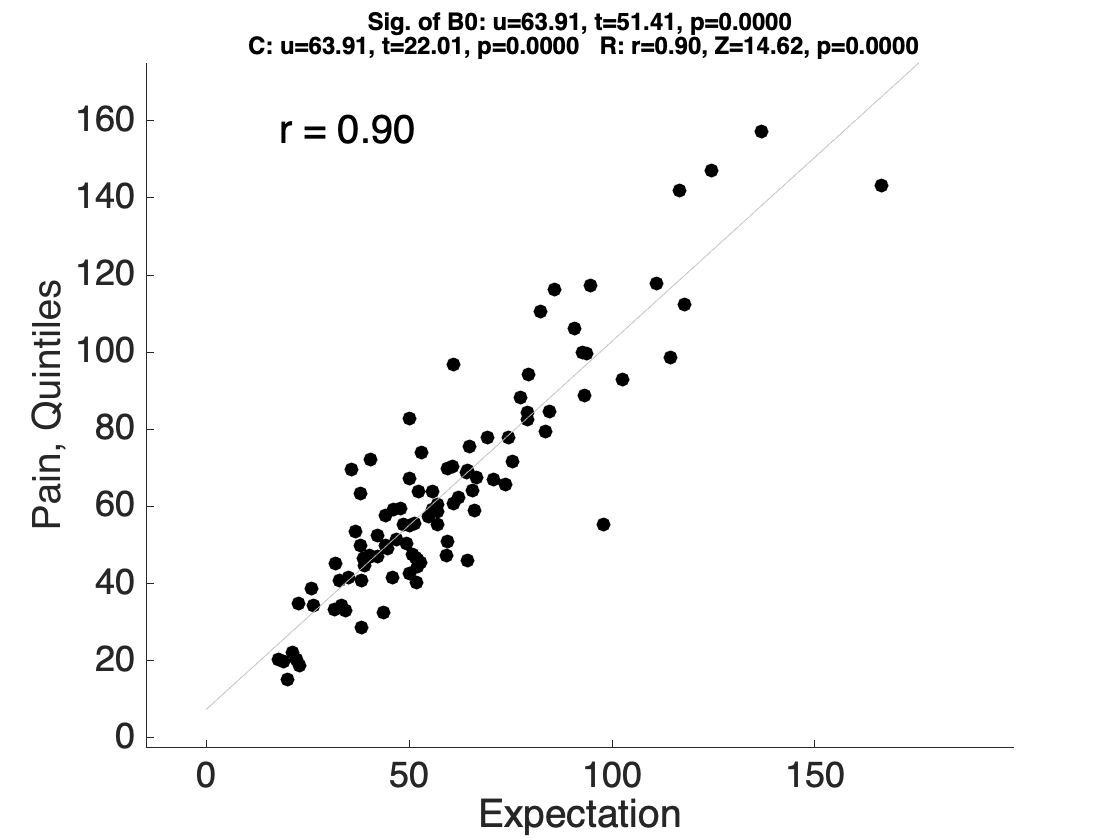


  figure; plot_correlation_samefig(meanx, meany, [], 'ko');
  xlabel('Expectation')
  ylabel('Pain, Quintiles')



create_figure('NPSpos vs. Pain');
  set(gca, 'FontSize', 20);
  han = line_plot_multisubject(model1_M, model1_Y, 'n_bins', 5);

Warnings:

____________________________________________________________________________________________________________________________________________
X: input cells with low varability:
17 29 35 44 50
Y: input cells with low varability:
15 43 45 58 89
____________________________________________________________________________________________________________________________________________

____________________________________________________________________________________________________________________________________________
Input data:
X scaling: No centering or z-scoring
Y scaling: No centering or z-scoring
                
Transformations:
No data transformations before plot
                                                                   
Correlations:                                                      
r = 0.19 across all observations, based on untransformed input data
                                                                
Stats on slopes after transformation, 

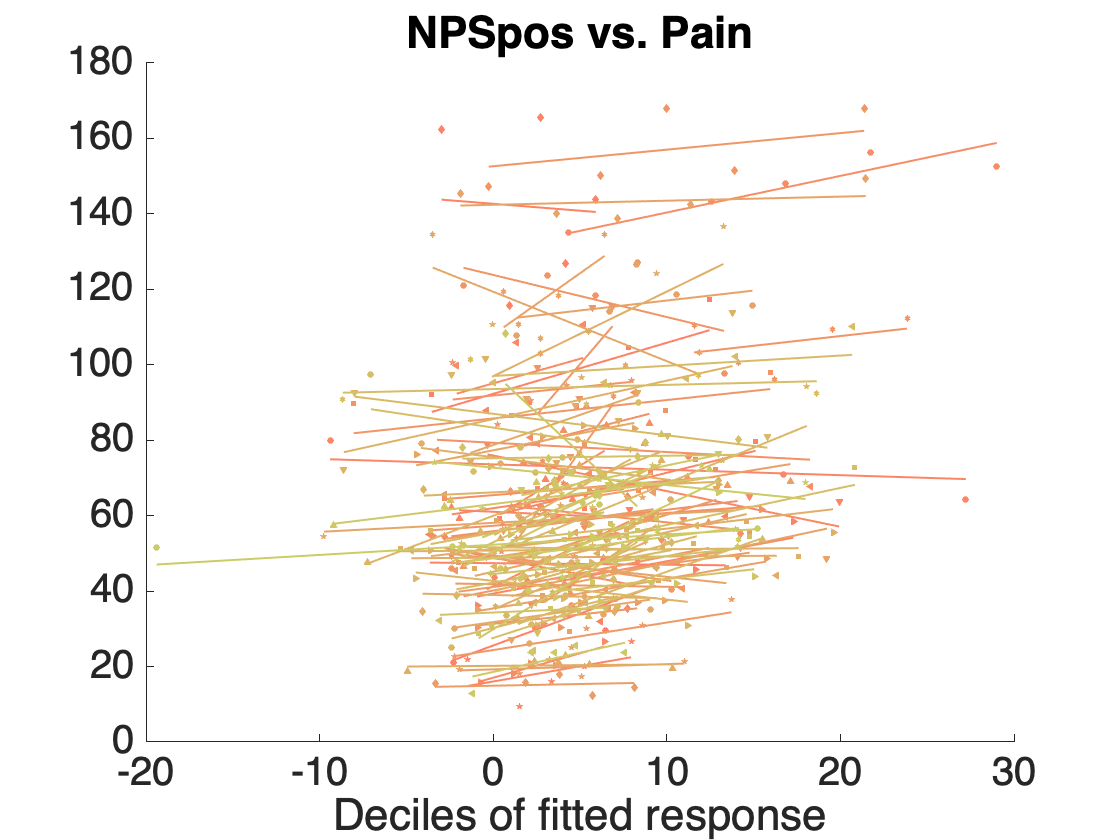

  title('NPSpos vs. Pain');
  xlabel('Deciles of fitted response');

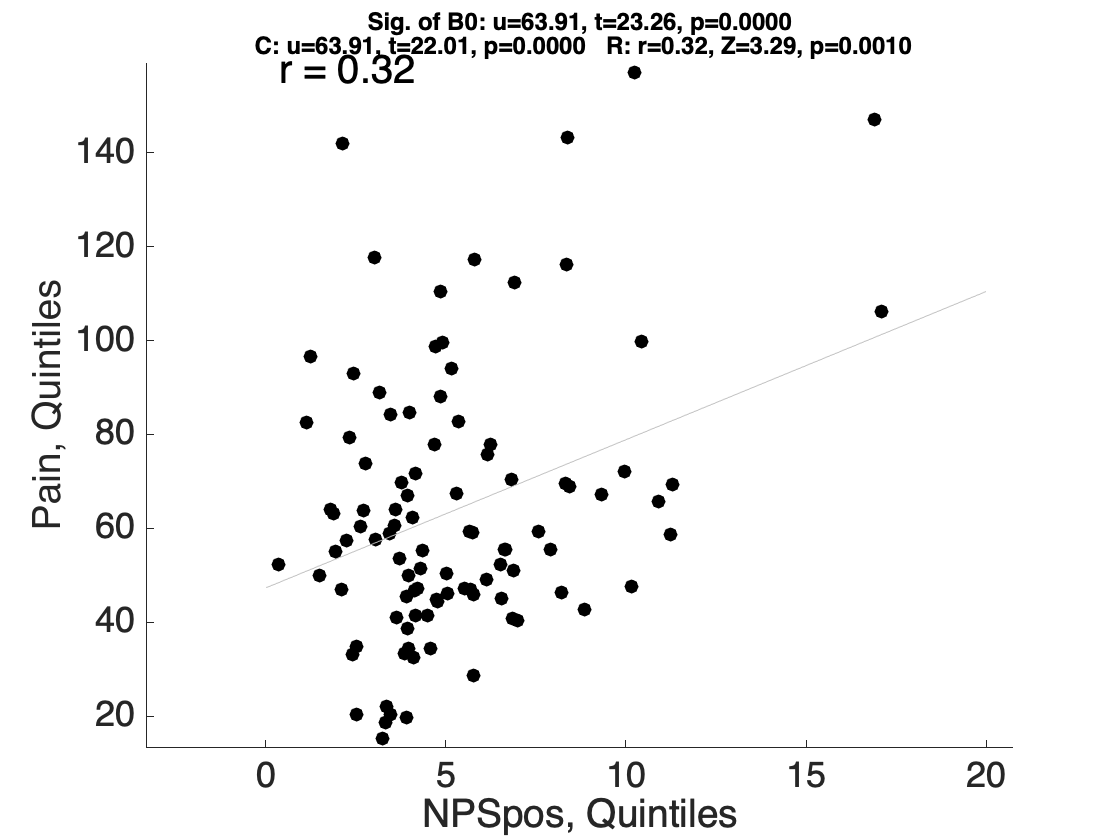


  figure; plot_correlation_samefig(meanm, meany, [], 'ko');
  xlabel('NPSpos, Quintiles')
  ylabel('Pain, Quintiles')



create_figure('Expectation vs. NPS');
  set(gca, 'FontSize', 20);
  han = line_plot_multisubject(model1_X, model1_M, 'n_bins', 5);

Warnings:

____________________________________________________________________________________________________________________________________________
X: input cells with low varability:
8 15 43 58 75
Y: input cells with low varability:
17 29 35 44 50
____________________________________________________________________________________________________________________________________________

____________________________________________________________________________________________________________________________________________
Input data:
X scaling: No centering or z-scoring
Y scaling: No centering or z-scoring
                
Transformations:
No data transformations before plot
                                                                   
Correlations:                                                      
r = 0.06 across all observations, based on untransformed input data
                                                                
Stats on slopes after transformation, s

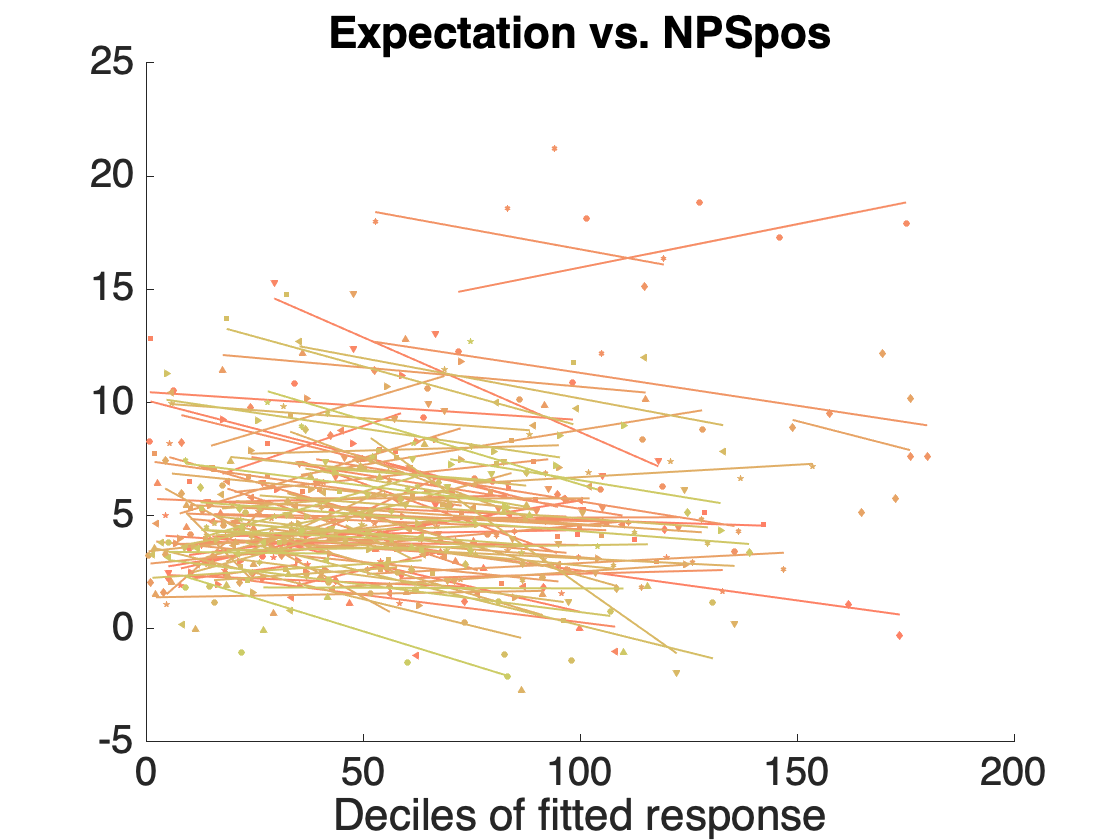

  title('Expectation vs. NPSpos');
  xlabel('Deciles of fitted response');


  figure; plot_correlation_samefig(meanx, meanm, [], 'ko');
  xlabel('Expectation, Quintiles')
  ylabel('NPSpos, Quintiles')

    


% partial correlations between expectancy, pain and NPSpos
partialr = partialcorr([meanx meany meanm]);

t = array2table(partialr, 'VariableNames', {'Expect' 'Pain' 'NPSpos'});
t

t = 3×3 table
     Expect      Pain       NPSpos 
    ________    _______    ________

           1    0.89341    0.030689
     0.89341          1     0.11784
    0.030689    0.11784           1


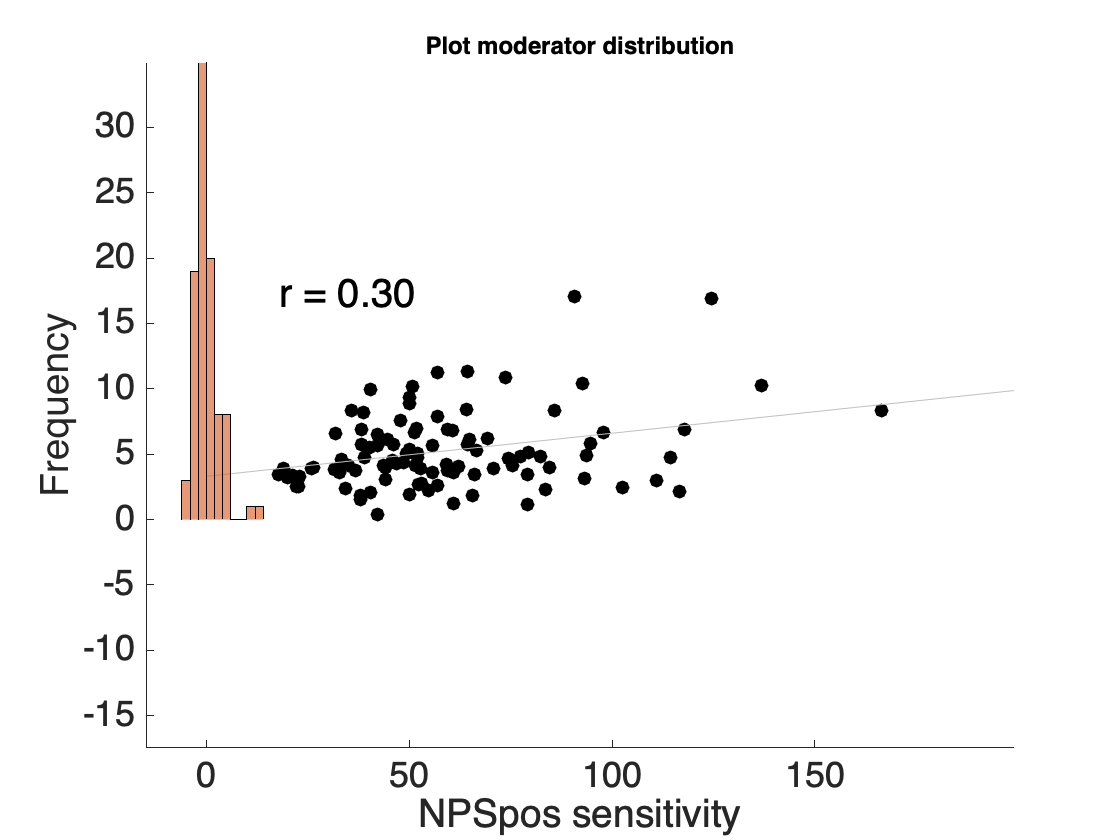


histogram(moderator);
xlabel('NPSpos sensitivity');
ylabel('Frequency');
title('Plot moderator distribution');